%L1.b. Frequency Domain Analysis

% Problem 1
% Consider the unity negative feedback closed loop system having open loop transfer function 
% G(s) = (omega_{n} ^ 2)/(s(s + 2xi*omega_{n}))
% Choose appropriate value of wn and zeta (xi). 
% Choose to be <0.707. 
% Obtain the closed loop transfer function.
% This is a typical second order system.

clc;
clear;
close all;
% Given values
wn = 27;
xi = 0.3;
% Transfer function
num = wn;
den = [1 2*xi*wn wn];
sys = tf(num,den)


sys =
 
         27
  -----------------
  s^2 + 16.2 s + 27
 
Continuous-time transfer function.
Model Properties


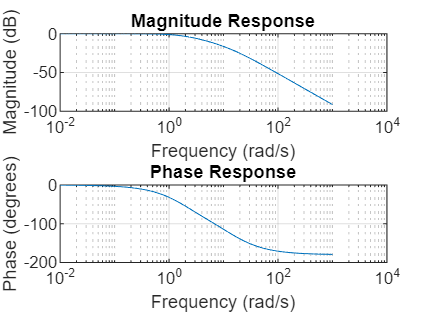

% Frequency range
w = logspace(-2,3,100);
% Frequency response
h = freqresp(sys,w);
% Real and imaginary parts
re = real(h(:));
img = imag(h(:));
% Magnitude
mag = sqrt(re.^2 + img.^2);
% Magnitude in dB
magdb = 20*log10(mag);
% Phase in radians
ph = atan2(img,re);
% Phase in degrees
phd = ph*180/pi;
figure
% Magnitude plot
subplot(2,1,1)
semilogx(w,magdb)
grid on
hold on
title('Magnitude Response')
xlabel('Frequency (rad/s)')
ylabel('Magnitude (dB)')
% Phase plot
subplot(2,1,2)
semilogx(w,phd)
grid on
hold on
title('Phase Response')
xlabel('Frequency (rad/s)')
ylabel('Phase (degrees)')

%L1.b. Frequency Domain Analysis

% Exercise 1
% Using Matlab command find the magnitude and phase angle
% of the system with transfer function
% G(s) = 5/(s + 2) at 3 rad/sec

% Transfer function coefficients
GNUM = [5];
GDEN = [1 2];
% Evaluate at s = j3
s = 3*j;
% Complex function evaluation
Gj3 = polyval(GNUM,s)/polyval(GDEN,s)

Gj3 = 0.7692 - 1.1538i

% Magnitude
magGj3 = abs(Gj3)

magGj3 = 1.3868

% Phase angle in degrees
phaseGj3 = angle(Gj3)*180/pi

phaseGj3 = -56.3099

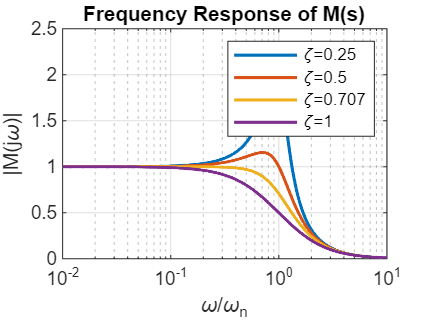

%L1.b. Frequency Domain Analysis

% Exercise 2
% Consider the standard second order transfer function
% M(s)=(omega_n^2)/(s^2+2*xi*omega_n*s+omega_n^2)
% Plot the frequency response for xi=0.25, 0.5, 0.707, 1

% Normalized frequency range
wv=logspace(-2,1,1000);

% Damping ratio values
z=[0.25 0.5 0.707 1];

figure
for k=1:4
    % Numerator coefficients
    mnum=[0 0 1];

    % Denominator coefficients
    mden=[1 2*z(k) 1];

    % Frequency response
    mjomega=freqs(mnum,mden,wv);

    % Magnitude response
    mmag=abs(mjomega);

    % Plot
    semilogx(wv,mmag,'LineWidth',1.5)
    hold on
end

title('Frequency Response of M(s)')
xlabel('\omega/\omega_n')
ylabel('|M(j\omega)|')
legend('\zeta=0.25','\zeta=0.5','\zeta=0.707','\zeta=1')
grid on